We compute SSM compute for an Oscillator Chain with cubic and quadratic nonlinearities

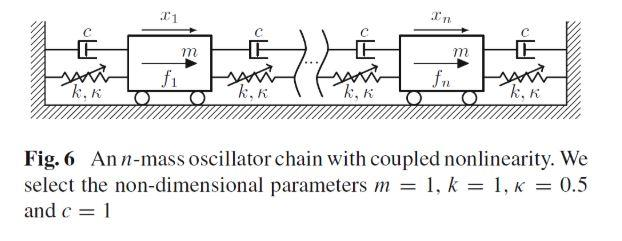

clear all; close all; clc

# Example setup

n = 10;
m = 1;
c = 0.1;
k = 1;
kappa2 = 0;
kappa3 = 0.5;
[M,C,K,fnl,~] = build_model(n,m,c,k,kappa2,kappa3);

# Dynamical System Setup

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

**Linear Modal analysis**

[V,D,W] = DS.linear_spectral_analysis(); % Linear Modal analysis

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.423148e-02
modal damping ratio for 2 mode is 2.817326e-02
modal damping ratio for 3 mode is 4.154150e-02
modal damping ratio for 4 mode is 5.406408e-02
modal damping ratio for 5 mode is 6.548607e-02

 The first 10 eigenvalues are given as 
  -0.0041 + 0.2846i
  -0.0041 - 0.2846i
  -0.0159 + 0.5632i
  -0.0159 - 0.5632i
  -0.0345 + 0.8301i
  -0.0345 - 0.8301i
  -0.0585 + 1.0797i
  -0.0585 - 1.0797i
  -0.0858 + 1.3069i
  -0.0858 - 1.3069i



We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} + \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


where excitation shape $\mathbf{f}_0$ is a combination of the first three modes as

Phi = real(V(1:10,1:2:end));
f_0 = 0.2*Phi(:,1)*1+Phi(:,2)*2+Phi(:,3);
epsilon = 1e-3;

Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

# Forced Response Curve in a Frequency Span

## SSM setup

**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     1
     4     2
     5     3
     6     4
     0     2
     1     3
     2     4
     3     5
     4     6
     4     1
     5     2
     6     3
     1     4
     2     5
     3     6

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0345 + 0.8301i
  -0.0345 + 0.8301i
  -0.0345 + 0.8301i
  -0.0345 - 0.8301i
  -0.0345 - 0.8301i
  -0.0345 - 0.8301i

sigma_out = 21
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     1     2
     2     3
     3     4

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0041 + 0.2846i
  -0.0041 + 0.2846i
  -0.0041 + 0.284

## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 5; % Approximation order
outdof = floor(n/2);


setup options

set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 200, 'nPsi', 200, 'rhoScale', 2)
set(S.FRCOptions, 'method','continuation ep')
set(S.FRCOptions, 'outdof',outdof)

**Specify frequency span**

omega = imag(D(1:2:end));
omegaRange = [0.8*omega(1) 1.2*omega(3)];

extract forced response curve

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     5     3
     5     4
     6     4
     0     2
     1     2
     1     3
     2     3
     2     4
     3     4
     3     5
     4     5
     4     6
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     3     0
     4     0
     4     1
     5     1
     5     2
     6     2
     6     3
     7     3
     0     3
     0     4
     1     4
     1     5
     2     5
     2     6
     3     6
     3     7
     4     0
     5     0
     5     1
     6     1
     6     2
     7     2
     7     3
     0     4
     0     5
     1     5
     1     6


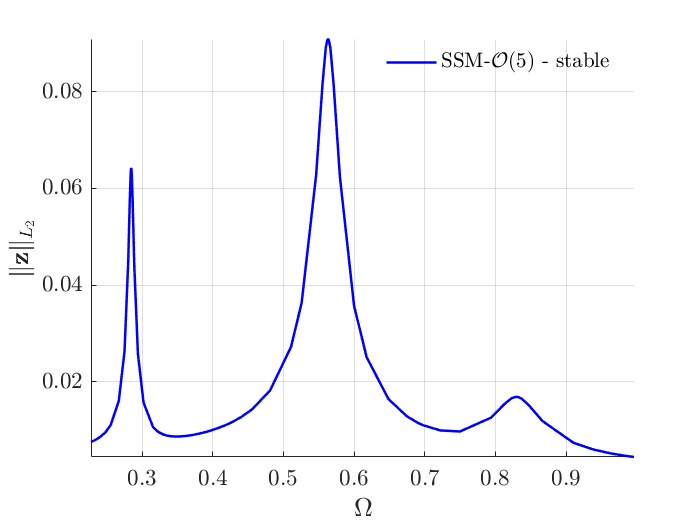

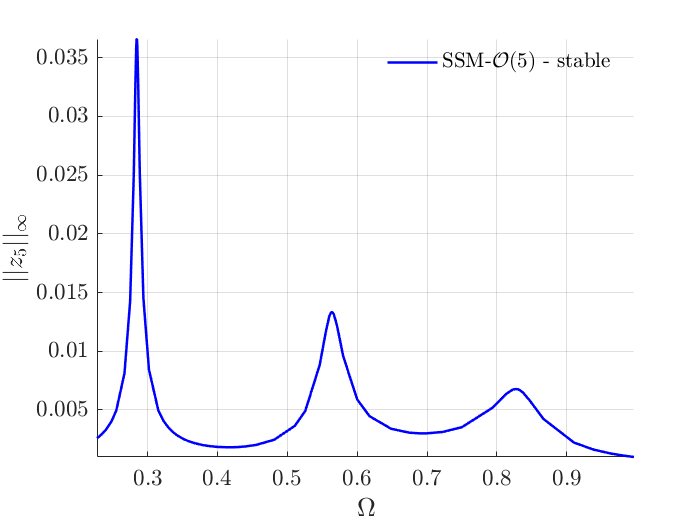

FRC = S.extract_FRC('freq',omegaRange,order);

figFRC = gcf;
